Detected Tag ID, Family: 5, tag36h11
Detected Tag ID, Family: 11, tag36h11


Detected Tag ID, Family: 5, tag36h11
Detected Tag ID, Family: 11, tag36h11
Detected Tag ID, Family: 5, tag36h11
Detected Tag ID, Family: 11, tag36h11
Detected Tag ID, Family: 5, tag36h11
Detected Tag ID, Family: 11, tag36h11


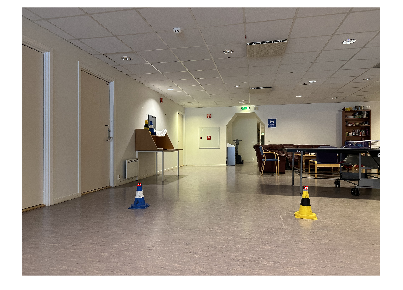

imgs_markers = ["left/L0035", "left/L0036", "right/R0035", "right/R0036"];
tagFamily = ["tag36h11","tagCircle49h12","tagCustom48h12","tagStandard41h12"];

% Initialize an empty matrix to store the loc data
allLoc = [];

for img = 1:length(imgs_markers)
    % Read the image
    imgPath = "/Users/elinehave/Library/CloudStorage/OneDrive-NTNU/8. semester/Robotsyn/RoboticVision-project/data/" + imgs_markers(img) + ".jpeg";
    img = imread(imgPath);
    
    % Check if the image was read correctly
    if isempty(img)
        disp("Failed to read image " + imgPath);
        continue;
    end
    
    % Detect April tags in the image
    [id,loc,detectedFamily] = readAprilTag(img,tagFamily);
    
    % Check if any April tags were detected
    if isempty(id)
        disp("No April tags detected in image " + imgPath);
        continue;
    end

    for idx = 1:length(id)
        % Display the ID and tag family
        disp("Detected Tag ID, Family: " + id(idx) + ", " ...
            + detectedFamily(idx));

        % Insert markers to indicate the locations
        markerRadius = 8;
        numCorners = size(loc,1);
        markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
        img = insertShape(img,"FilledCircle",markerPosition,Color="red",Opacity=1);
    end
    
    % Append the loc data from the current image to the allLoc matrix
    allLoc = [allLoc; loc];
    
    % Show the image with the April tags detected
    imshow(img)
end


% Save the matrix to a CSV file without the header row
dlmwrite('detectedAprilTags.csv', allLoc, 'delimiter', ',', 'precision', '%.4f', 'newline', 'pc');
